# Lecture: MATLAB Review 1 code

Kim Xu

MAE 284

clear, clc

## Basic Math

format short

### Jenny's Constant: $\left(7^{\frac{e}{1}-\frac{1}{e}} -9\right)\pi^2$

jenny=(7^(exp(1)-1/exp(1))-9)*pi^2

jenny = 867.5309

### Estimate for g:  $6+\ln \left(45\right)$

g=6+log(45)

g = 9.8067

### Avogadro's Number: ${69}^{\pi^{\sqrt{5}} }$

avogadro=69^(pi^sqrt(5))

avogadro = 6.0219e+23

## Array fun

### Creating arrays

An array with 2, 8, 14 and 20 in a row

y = [2, 8, 14, 20]  % commas not necessary

y =      2     8    14    20


An array with 6, 2, 5 in a column

z = [6; 2; 5]

z =      6
     2
     5


A 3x3 array with 1, 2, 3 in the first row, 

                           1, 4, 9 in the second row

                           1, 8, 27 in the third row

q = [1 2 3; 1 4 9; 1 8 27]

q =      1     2     3
     1     4     9
     1     8    27


### Equally spaced arrays

an array starting at 1 ending at 10 with a step size of 1

a = 1:10

a =      1     2     3     4     5     6     7     8     9    10


an array starting at 3 ending at 11 stepping by 2

v = 3:2:11

v =      3     5     7     9    11


an array starting at 1 ending at 4 with 6 points

v = linspace(1,4,6)

v =     1.0000    1.6000    2.2000    2.8000    3.4000    4.0000


an array starting at 6 ending at 2 with 100 points

v = linspace(6,2)

v =     6.0000    5.9596    5.9192    5.8788    5.8384    5.7980    5.7576    5.7172    5.6768    5.6364    5.5960    5.5556    5.5152    5.4747    5.4343    5.3939    5.3535    5.3131    5.2727    5.2323    5.1919    5.1515    5.1111    5.0707    5.0303    4.9899    4.9495    4.9091    4.8687    4.8283    4.7879    4.7475    4.7071    4.6667    4.6263    4.5859    4.5455    4.5051    4.4646    4.4242    4.3838    4.3434    4.3030    4.2626    4.2222    4.1818    4.1414    4.1010    4.0606    4.0202


### Array Math

x1 is an array of integers from 1 to 5

x1=1:1:5

x1 =      1     2     3     4     5


x2 is an array with 5 values between 0 and 3

x2=linspace(0,3,5)

x2 =          0    0.7500    1.5000    2.2500    3.0000


Square the values in x1

x1.^2

ans =      1     4     9    16    25


### Getting info about Arrays

3rd element in y

y(3)

ans = 14

What is the index for the value 9 in q?

q(2,3)

ans = 9

2nd through 3rd columns in last row of q

q(end,2:3)

ans =      8    27


Get the 2nd column of q

q(:,2)

ans =      2
     4
     8


how many elements in y?

length(y)

ans = 4

### Manipulating Arrays

A has the integers 1 and 2 in a row

a=[1,2]

a =      1     2


Add 3 & 4 to the end of the row

a=[a,3,4]

a =      1     2     3     4


The 2nd row has the cubes of the 1st row

a=[a;a.^3]

a =      1     2     3     4
     1     8    27    64


Change the 2nd row to 2 times the 1st

a(2,:)=2*a(1,:)

a =      1     2     3     4
     2     4     6     8


Make the 3rd row all 5s

a(3,:)=5

a =      1     2     3     4
     2     4     6     8
     5     5     5     5


Swap rows and columns

a=a'

a =      1     2     5
     2     4     5
     3     6     5
     4     8     5


## Plotting

### Basic plotting

**Data:**

t is 10 through 60 by 10s (in minutes)      c is 3.4, 2.6, 1.6, 1.3, 1.0, 0.5 (in ppm)

t_data = 10:10:60;  % TO COMPLETE time in minutes from data
c_data = [3.4 2.6 1.6 1.3 1 0.5]; % concentration in ppm from data

**Theoretical:**

t from 0-70 minutes  $c=4\ldotp 84e^{-0\ldotp 034t}$

t_theory = linspace(0,70); % TO COMPLETE time in minutes
c_theory = 4.84*exp(-0.034*t_theory); % concentration in ppm in theory

Plot data with red diamonds and function with green, dashed line

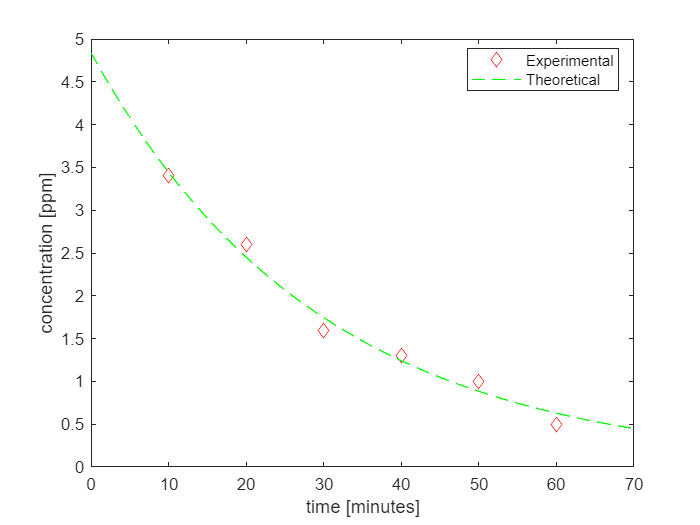

plot(t_data,c_data,"rd",t_theory,c_theory,"g--")
xlabel 'time [minutes]'
ylabel 'concentration [ppm]'
legend('Experimental','Theoretical','location','best')

### Subplots

Air density $\rho =1\ldotp 223\;\frac{kg}{m^2 }$

data = [83.6 60.2 72.1 91.1 92.9 65.3 80.9;      % mass [kg]
        53.4 48.5 50.9 55.7 54 47.7 51.1;        % v_t [m/s]
        0.455 0.402 0.452 0.486 0.531 0.475 0.487];  % A [m^2]

g = 9.81; % gravity in m/s/s
rho = 1.223; % air density [kg/m^3]

Define these variables from the data: $m,v_t ,A$

m = data(1,:);  % mass
v_t = data(2,:); % terminal velocity
A = data(3,:);   % frontal area

calculate drag coefficient: $C_D =\frac{2\textrm{mg}}{\rho {\textrm{Av}}_t^2 }$

Cd = 2*m*g./(rho*A.*v_t.^2); % WHERE DO DOTS GO?

Put drag coefficient in the 4th row of data

data(4,:) = Cd;

**Plot **$A$** versus **$m$** above a plot of **$C_d$** versus **$m$ 

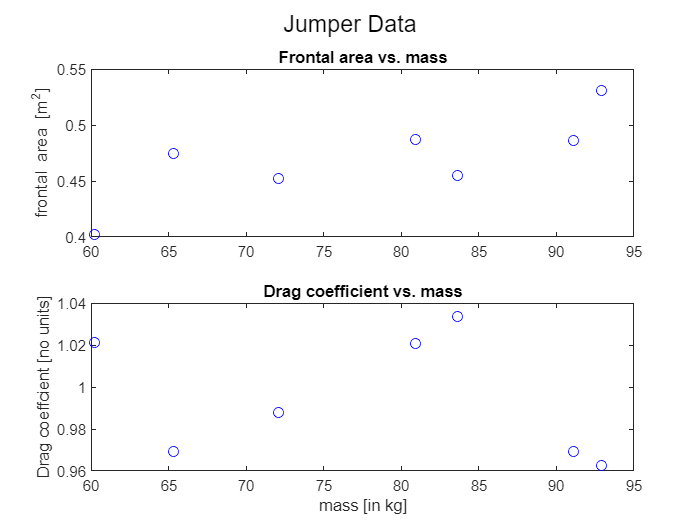

subplot(2,1,1)
plot(m, A, 'bo')
ylabel 'frontal area [m^2]'
title 'Frontal area vs. mass'
subplot(2,1,2)
plot(m, Cd, 'bo')
xlabel 'mass [in kg]'
ylabel 'Drag coeffcient [no units]'
title 'Drag coefficient vs. mass'
sgtitle 'Jumper Data'